resolution = 1200;

a11 = -0.4734; b10= (1-0.4734)/2; % not correct scale factor
a21=-1.0625; a22=+0.3498;
b21=0.5470; b22=1; b20= (1-1.0625+0.3498)/(1+0.5470+1); % not correct scale factor

a31 = -1.3811; a32 = 0.7130; b31=-0.3959; b30 = (1-1.3811+0.7130)/(1-0.3959+1);

w1=0; % registers for filter 1
w2=[0 0]; % registers for filter 2
w3=[0 0]; % registers for filter 3

x=[1 zeros(1,100)]; % Input time Series

y_1=zeros(1,101); % output time Series, Filter 1
y_2=zeros(1,101); % output time Series, Filter 2
y_3=zeros(1,101); % output time Series, Filter 3

for n=1:100 % for loop
    sm1=x(n)-a11*w1; % input sum, filter 1
    s1 =sm1+w1; % output sum, filter 1
    y_1(n)=b10*s1; % scale filter output, filter 1
    w1=sm1; % update register, filter 1

    sm2=y_1(n)-a21*w2(1)-a22*w2(2); % input sum, filter 2
    s2 =sm2+b21*w2(1)+b22*w2(2); % output sum, filter 2
    y_2(n)=b20*s2; % scale filter output, filter 2
    w2=[sm2 w2(1)]; % update registers, filter 2

    sm3=y_2(n)-a31*w3(1)-a32*w3(2); % input sum, filter 2
    s3 =sm3+b31*w3(1)+w3(2); % output sum, filter 2
    y_3(n)=b30*s3; % scale filter output, filter 2
    w3=[sm3 w3(1)]; % update registers, filter 2
end

## Plots for $h_1[n]$

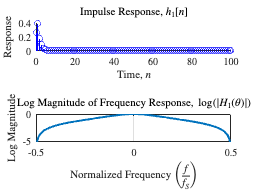

figure()
subplot(2,1,1)
hold on
stem(0:1:100,y_1,'b')
title('Impulse Response, $h_1[n]$')
ylabel('Response')
xlabel('Time, $n$')
%axis([0 100 -0.1 0.4])
hold off

b = [b10 b10];
a = [1 -0.4734];
hold on
[H,~]=freqz(b,a,200,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/200:0.5-1/200);
subplot(2,1,2);
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
%axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response, $\log(|H_1(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')


% exportgraphics(gcf, 'TeX/images/3B_H1.png', 'Resolution',resolution);

## Plots for $h_2[n]$

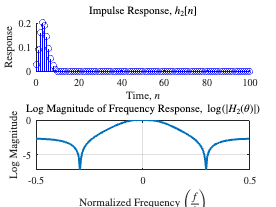


figure()
subplot(2,1,1)
hold on
stem(0:1:100,y_2,'b')
title('Impulse Response, $h_2[n]$')
ylabel('Response')
xlabel('Time, $n$')
%axis([0 100 -0.1 0.4])
hold off

b = [b20 b20*0.5470 b20];
a = [1 -1.0625 0.3498];
hold on
[H,~]=freqz(b,a,200,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/200:0.5-1/200);
subplot(2,1,2);
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
%axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response, $\log(|H_2(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')


% exportgraphics(gcf, 'TeX/images/3B_H2.png', 'Resolution',resolution);

## Plots for $h_3[n]$

figure()
subplot(2,1,1)
hold on
stem(0:1:100,y_3,'b')
title('Impulse Response, $h_3[n]$')
ylabel('Response')
xlabel('Time, $n$')
%axis([0 100 -0.1 0.4])
hold off

b = [b30 b30*0.3959 b30];
a = [1 -1.3811 0.7130];
hold on
[H,~]=freqz(b,a,200,'whole');
if isinf(H)
    H(1) = H(2);
end
frq=(-0.5:1/200:0.5-1/200);
subplot(2,1,2);
plot(frq,log(fftshift(abs(H))/max(abs(H))),'linewidth',2)
grid on
%axis([-0.5 0.5 -8 1.1])
title('Log Magnitude of Frequency Response, $\log(|H_1(\theta)|)$')
xlabel('Normalized Frequency $\left(\frac{f}{f_S}\right)$')
ylabel('Log Magnitude')


% exportgraphics(gcf, 'TeX/images/3B_H3.png', 'Resolution',resolution);

## Verification

h2=filter(b10*[1.0 1.0 0.0],[1.0 -0.4743 0.0],[1 zeros(1,100)]);
figure()
hold on
stem(0:1:100,h2,'b')
title('Verified Impulse Response, $h_1[n]$')
ylabel('Response')
xlabel('Time, $n$')
hold off


% exportgraphics(gcf, 'TeX/images/3C_H1.png', 'Resolution',resolution);

figure()
stem(0:1:100, y_1 - h2, 'filled','r')
title('Error, $$h_{1,{computed}}[n] - h_{1,{filter}}[n]$$')
ylabel('Error')
xlabel('Time, n')


% exportgraphics(gcf, 'TeX/images/3C_H1_error.png', 'Resolution',resolution);

h2=filter(b20*[1.0 0.5470 1.0],[1.0 -1.0625 0.3498],h2);
figure()
hold on
stem(0:1:100,h2,'b')
title('Verified Impulse Response, $h_2[n]$')
ylabel('Response')
xlabel('Time, $n$')
hold off


% exportgraphics(gcf, 'TeX/images/3C_H2.png', 'Resolution',resolution);

figure()
stem(0:1:100, y_2 - h2, 'filled','r')
title('Error, $$h_{2,{computed}}[n] - h_{2,{filter}}[n]$$')
ylabel('Error')
xlabel('Time, n')


% exportgraphics(gcf, 'TeX/images/3C_H2_error.png', 'Resolution',resolution);

h2=filter(b30*[1.0 -0.3959 1.0],[1.0 -1.3811 0.7130],h2);
figure()
hold on
stem(0:1:100,h2,'b')
title('Verified Impulse Response, $h_3[n]$')
ylabel('Response')
xlabel('Time, $n$')
hold off


% exportgraphics(gcf, 'TeX/images/3C_H3.png', 'Resolution',resolution);

figure()
stem(0:1:100, y_3 - h2, 'filled','r')
title('Error, $$h_{3,{computed}}[n] - h_{3,{filter}}[n]$$')
ylabel('Error')
xlabel('Time, n')


% exportgraphics(gcf, 'TeX/images/3C_H3_error.png', 'Resolution',resolution);